clear

addpath('matlab_functions\')

#### Compare FEM and analytical solution

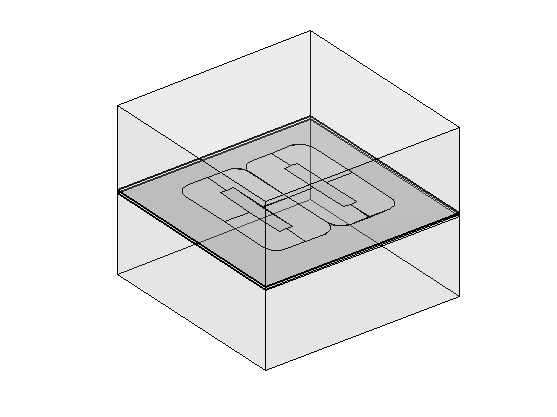

Model = myModel;
freq = 100; % (Hz)
mesh_size = 5; % 1:finest 9:coarsest

lim = 30e-3;
[x,y,z] = ndgrid( ...
    linspace(-lim, lim, 31), ...
    linspace(-lim, lim, 31), ...
    -1.5e-3);

Model = ComsolInterface('Build', Model);
ComsolInterface('PlotGeometry', Model);

tic
ComsolInterface('Solve', Model, freq, mesh_size);
toc

Elapsed time is 117.805853 seconds.


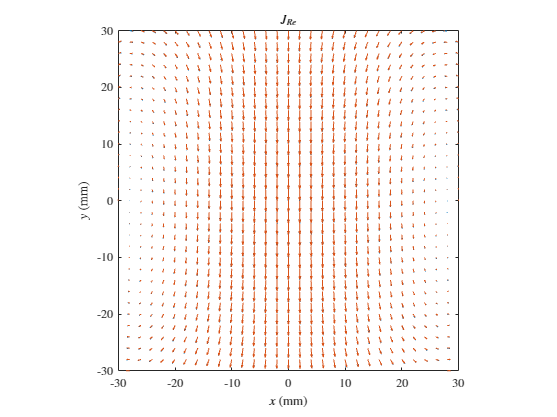

error: 3.41772%

[J1x,J1y] = ComsolInterface('EvaluateField', Model, {'Jx' 'Jy'}, x,y,z);

coilAbovePlate = CoilAbovePlate3D(Model.coil, Model.layers, 'TruncateWidth',Model.comsol.truncate_width);
[J2x,J2y] = coilAbovePlate.EvaluateField({'Jx' 'Jy'}, x,y,z, 2*pi*freq);

CompareField(x,y, real(J1x),real(J1y), real(J2x),real(J2y), '$J_{Re}$')

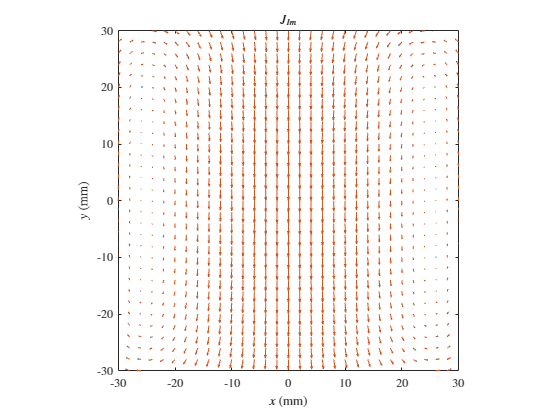

error: 1.49721%

CompareField(x,y, imag(J1x),imag(J1y), imag(J2x),imag(J2y), '$J_{Im}$')

#### 3D view

figure
drawModel(Model)

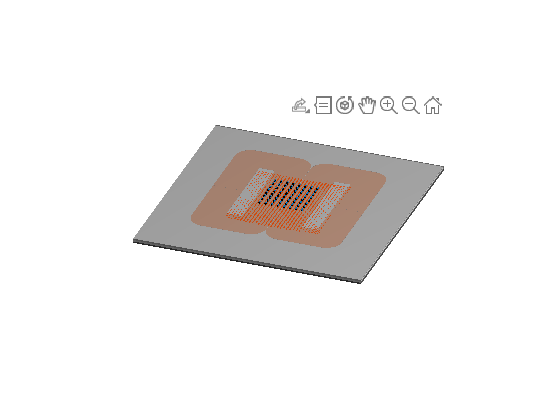


quiver(x, y, real(J1x), real(J1y))

view(20,30)
camlight

function CompareField(x,y, E1x,E1y, E2x,E2y, titlestr)

x_ = unique(x);
E_ = [reshape(E1x,1,[]); reshape(E1y,1,[])];
scale = (x_(2) - x_(1)) * 1e3 / max(vecnorm(E_));

figure
hold on
quiver(x*1e3, y*1e3, E1x*scale, E1y*scale, 'off')
quiver(x*1e3, y*1e3, E2x*scale, E2y*scale, 'off')
xlim([min(x,[],'all') max(x,[],'all')] * 1e3)
ylim([min(y,[],'all') max(y,[],'all')] * 1e3)
axis square
box on
title(titlestr, 'Interpreter','latex')
xlabel('$x$ (mm)', 'Interpreter','latex')
ylabel('$y$ (mm)', 'Interpreter','latex')

error = sqrt((E1x-E2x).^2 + (E1y-E2y).^2);
base = sqrt(E1x.^2 + E1y.^2);

fprintf("error: %g%%", mean(error) / mean(base) * 100)

end

function drawModel(Model)

hold on

comsolModel = mphopen(Model.comsol.coil_filename, 'temp');
mphgeom(comsolModel, 'geom1', 'edgemode','off', 'facecolor',[0.9 0.3 0], 'facealpha',0.3)
axis off
title("")

colors{1} = [0.8 0.8 0.8];
colors{2} = [0.95 0.95 0.95];
colors{3} = [0.4 0.4 0.4];

bottom_z = 0;
for k = 1:length(Model.layers)-1
    width = Model.comsol.truncate_width;
    thickness = Model.layers{k}.thickness;
    bottom_z = bottom_z - thickness;

    drawBlock(0, 0, bottom_z+thickness/2, width, width, thickness, colors{k})
end

l = 1e-3;
for k = 1:size(Model.sensors.positions, 2)
    pos = Model.sensors.positions(:,k);
    drawBlock(pos(1), pos(2), pos(3), l, l, l, 'k')
end

r = Model.sensors.positions;
v = Model.sensors.axes * l * 2;
quiver3(r(1,:), r(2,:), r(3,:), v(1,:), v(2,:), v(3,:), 'off', 'LineWidth',1)

end

function drawBlock(cx,cy,cz, dx,dy,dz, color)

x = [-dx dx dx -dx -dx] / 2;
x = [x; x] + cx;
y = [-dy -dy dy dy -dy] / 2;
y = [y; y] + cy;
z = [dz; -dz] .* ones(1,5) / 2 + cz;

surf(x, y, z, 'FaceColor',color, 'EdgeColor','none')  
patch(x', y', z', color, 'EdgeColor','none')

end